# Tall wind profile validation of ERA5, NORA3 and NEWA, using lidar observations

The matlab live script reproduces some of the results presented in Cheynet et al. (2024). This study aims to help future large offshore wind turbines and airborne wind energy systems by providing insights into wind speeds at much  higher altitudes than previously examined. We assessed three wind models (ERA5, NORA3, and NEWA) to predict wind speeds up to 500 m. Using lidar data from Norway and the North Sea, we found that ERA5 excels offshore, while NORA3 performs best onshore. However, the performance of the  models depends on the locations and the evaluation criteria.

## The wind model databases

In this study, the focus is on the ERA5 reanalysis, the European wind atlases NEWA and NORA3. ERA5 provides global hourly data since 1940 at approximately 31 km resolution. NEWA was released in 2019 and provides data at about 3 km resolution with 30-minute intervals covering 1989–2018 at altitudes from 10 to 500 m. NORA3 offers hourly wind data at 3 km resolution from 1961 onward at heights ranging from 10 to 750 m.

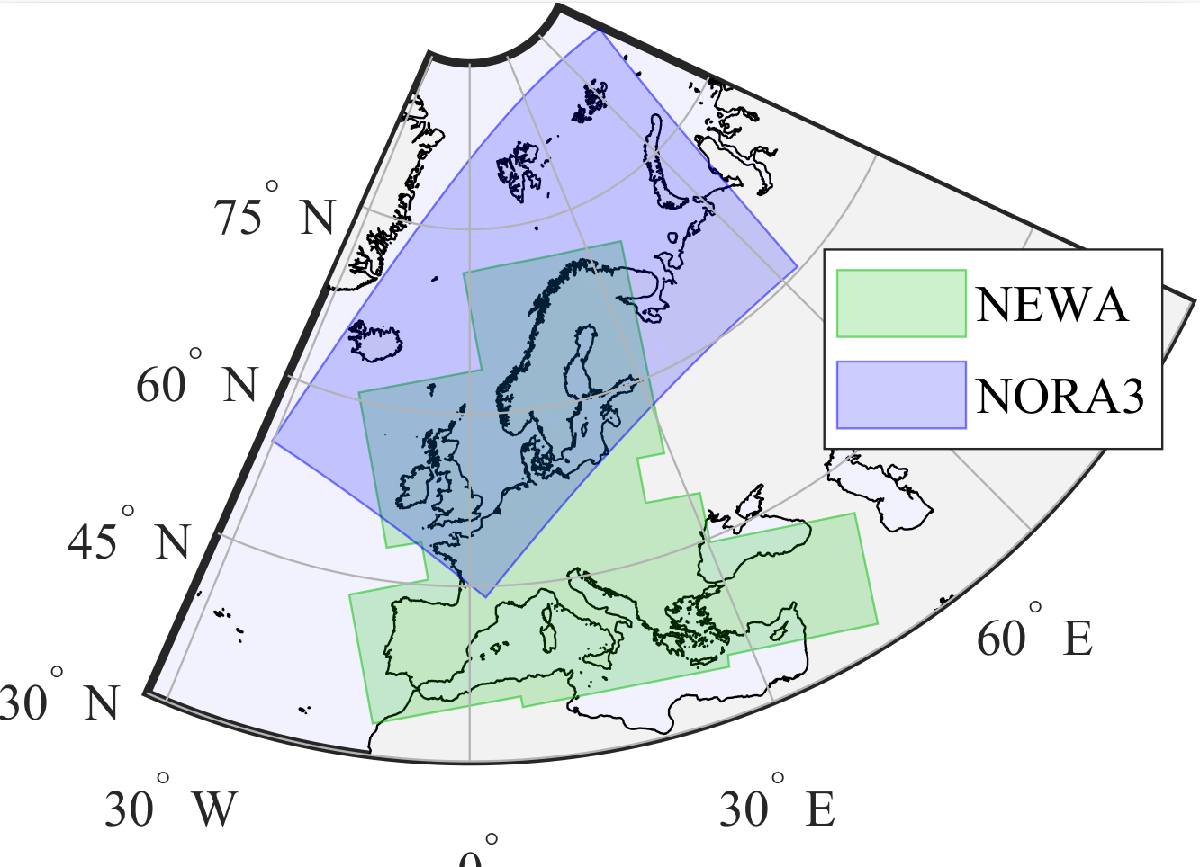

## The measurement sites

The wind measurement campaigns took place at five locations covered by the ERA5, NORA3, and NEWA datasets. These included two offshore platforms (FINO1 and FINO3), two coastal sites (Sola and Lista airports in Norway), and one mountainous site (Bjerkreim, Norway). The offshore platforms were more than 40 km from the coast, while the coastal sites were just a few kilometres inland, where changes in surface roughness affected wind flow. FINO1, located near wind farms, may further be used to document how wake effects impact lidar measurements. Doppler wind lidars (DWLs) were used to measure wind speeds at heights between 40 m and up to 3000 m. Offshore sites had fewer disturbances, while Bjerkreim’s mountainous terrain made wind conditions more complex. Some campaigns lasted over a year, while others were shorter. The study focused on comparing wind atlas data with tall wind profiles from the DWL instruments.

The location of the five sites is presented below:

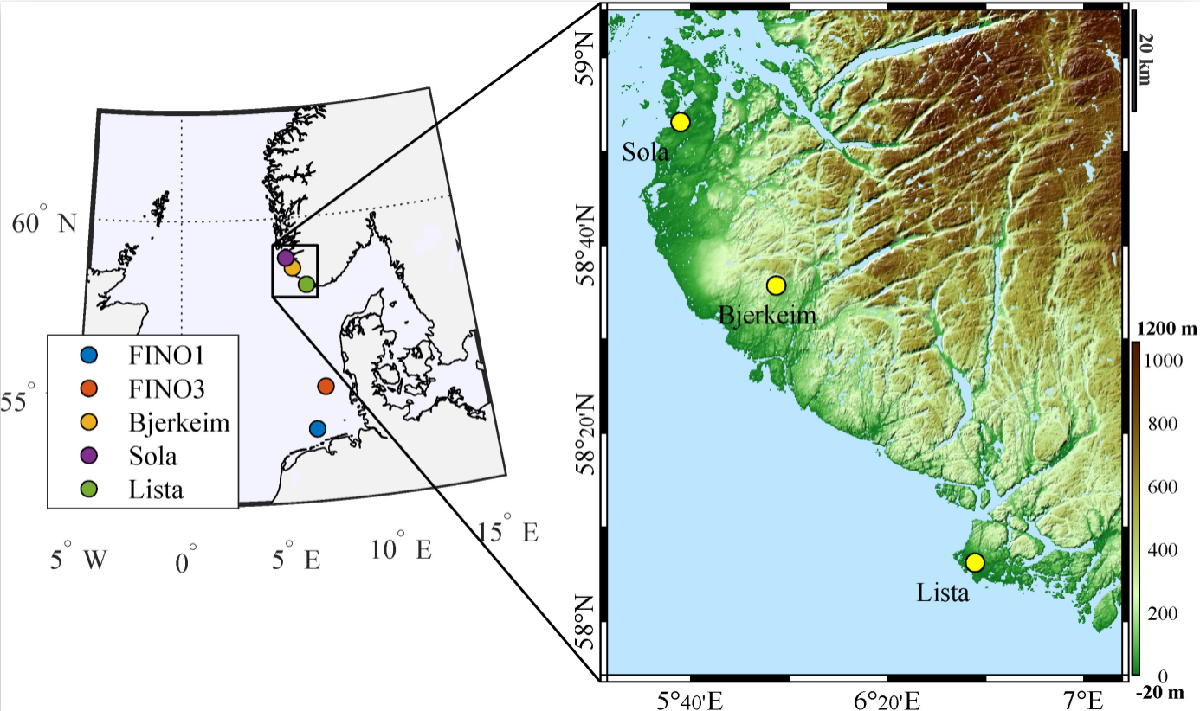

## Instrumentation

The five measurement campaigns used DWLs operating in Doppler Beam Swinging (DBS) mode to capture wind speed profiles at various heights. The WindCube 100S and WLS70 lidars were deployed at offshore and coastal sites, while the WindCube V1 was used in the mountainous Bjerkreim area. The instruments had different range gates, affecting their spatial resolution, with values between 20 m (Bjerkreim) and 100 m (Lista). Measurement heights varied by location, from a minimum of 40 m (Bjerkreim) to a maximum of over 3500 m (FINO1).

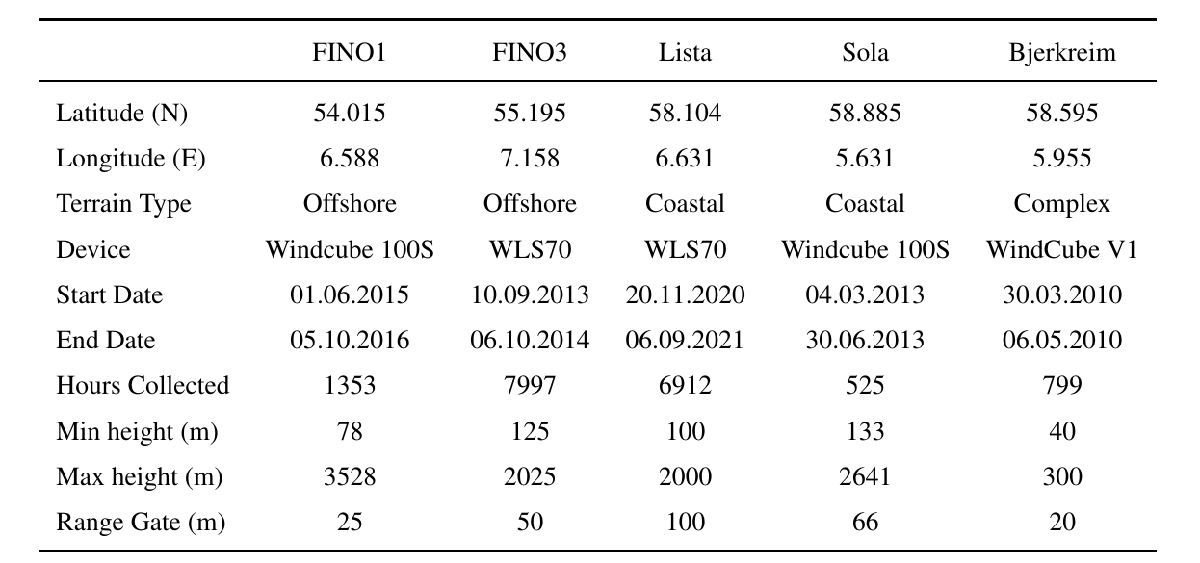

**references**

Cheynet, E., Diezel, J. M.,  Haakenstad, H., Breivik, Ø., Peña, A., & Reuder, J. (2024). Tall  Wind Profile Validation Using Lidar Observations and Hindcast Data. *Wind Energy Science Discussions*, *2024*, 1-29.

## Folder organisation

The repository contains the livescript "Documentation.mlx"

The repository contains five .mat files, which are used to compare directly the model databases with the ldiar data.

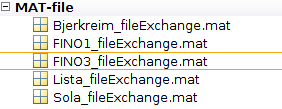

The repository contains also the "extended" wind speed databased, including non-overlapping periods, non-linear regression with  the Deaves and Harris model, wind direction. For the NORA3 data, there are also additional variables, such as temperature profiles. These data are in the following folders

## Data organization

The repository contains .mat files: [Location]_fileExchange.mat, which contains four structures variables. The variables ERA5, NEWA and NORA3 have been resampled in space and time to align with the lidar data LIDAR.

**Model data**

ERA5, NEWA and NORA3 contains three fields each: height (z), wind speed (U), wind direction (D), time (datetime) and time (datenum). Python can read the time_datenum but not the matlab datetime format. 

**Lidar data**

The lidar data contains the CNR 8carrier to noise ratio), wind speed (U), wind direction (Wdir), time (datetime),height (z) and time_datenum (double)

## Matlab Visualization

### Time series visualization

 I have interpolated the vertical mean wind speed profiles at multiple heights, overlapping with those from the lidar data. The visualziation simply overlap the lidar data with the extended wind speed databases, contained in the folder data_ERA5, data_NEWA and data_NORA3.

clearvars;close all;clc;
myLoc = {'FINO1','FINO3','Bjerkreim','Sola','Lista'};
zTarget = 200; % height at which we want to visualzie the time series

figure('position',[500 583         1100         200*numel(myLoc)])
tiledlayout(numel(myLoc),1,'TileSpacing','tight')

for ii = 1:numel(myLoc)
    nexttile
    defaultColors = get(gca, 'ColorOrder');
    load([myLoc{ii},'_fileExchange.mat'],'LIDAR');

    NORA3 = load(['data_NORA3/',myLoc{ii},'_NORA3.mat'],'time','newU','z');
    ERA5 = load(['data_ERA5/',myLoc{ii},'_ERA5.mat'],'time','newU','z');

    [~,indZ_ERA5]=min(abs(ERA5.z-zTarget));
    [~,indZ_NORA3]=min(abs(NORA3.z-zTarget));
    [~,indZ_lidar]=min(abs(LIDAR.z-zTarget));

    time = LIDAR.time;
    if strcmpi(myLoc{ii},'Bjerkreim'),    LIDAR.U(LIDAR.U>27) = nan;    end


    plot(ERA5.time,ERA5.newU(indZ_ERA5,:),'color',defaultColors(1,:),'linewidth',1.0);
    hold on
    plot(NORA3.time,NORA3.newU(indZ_NORA3,:),'color',defaultColors(2,:),'linewidth',1.0);

    if strcmpi(myLoc{ii},'LISTA'),
        warning('NEWA not available for Lista')
    else
        NEWA = load(['data_NEWA/',myLoc{ii},'_NEWA.mat'],'time','newU','z');
        [~,indZ_NEWA]=min(abs(NEWA.z-zTarget));
        plot(NEWA.time,NEWA.newU(indZ_NEWA,:),'color',defaultColors(3,:),'linewidth',1.0);
    end

    indOK = find(~isnan(LIDAR.U(:,indZ_lidar)));
    x = time(indOK);
    y = LIDAR.U(indOK,indZ_lidar);

    indDisjoint = find(abs(diff(x'))>hours(12));
    if numel(indDisjoint)>1
        for pp=1:numel(indDisjoint)+1
            if pp==1
                indStart = 1;
                indEnd = indDisjoint(pp)-1;
            elseif pp==numel(indDisjoint)+1
                indStart = indDisjoint(pp-1)+1;
                indEnd = numel(x);
            else
                indStart = indDisjoint(pp-1)+1;
                indEnd = indDisjoint(pp)-1;
            end

            plot(x(indStart:indEnd),y(indStart:indEnd),'k','linewidth',1.0)
        end
    else

    end


    xlim(time([1 end]))
    if ii==1
        legend('ERA5','NORA3','NEWA','Measured','location','northoutside','Orientation','horizontal')
    end
    grid on
    ylabel('$\overline{u}$ (m s$^{-1}$)','interpreter','latex')
    box on
    myText = sprintf('$z = $ %2.0f m',round(LIDAR.z(indZ_lidar)));
    label(myText,0.97,0.97,'alignment','right','verticalalignment','top');
    myText = sprintf('Loc: %s',myLoc{ii});
    label(myText,0.80,0.97,'alignment','right','verticalalignment','top');
    xtickformat('MMM-yyyy')
end

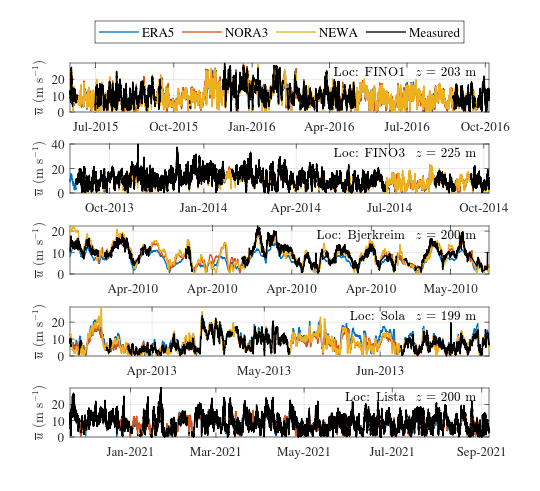


set(findall(gcf,'-property','FontSize'),'FontSize',10,'FontName','Times')

set(gcf,'color','w')

### Simple comparison of wind speed data

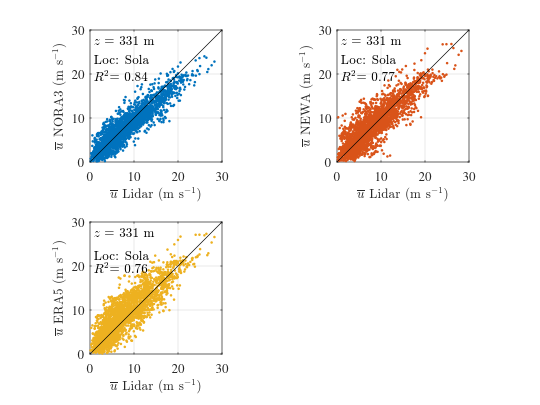

clearvars;close all;clc;
myLoc = {'Sola'};
zTarget = 300; % height at which we want to visualzie the time series

clf;close all
figure
tiledlayout(numel(myLoc),3,'TileSpacing','tight')
defaultColors = get(gca, 'ColorOrder');
for ii = 1:numel(myLoc)
    load([myLoc{ii},'_fileExchange.mat'],'LIDAR','ERA5','NEWA','NORA3');
    [~,indZ_ERA5]=min(abs(ERA5.z-zTarget));
    [~,indZ_NORA3]=min(abs(NORA3.z-zTarget));

    [~,indZ_lidar]=min(abs(LIDAR.z-zTarget));
    if strcmpi(myLoc{ii},'Bjerkreim'),    LIDAR.U(LIDAR.U>27) = nan;    end

    if strcmpi(myLoc{ii},'LISTA'),
        warning('NEWA not available for Lista')
        nexttile
        plot(LIDAR.U(:,indZ_lidar),NORA3.U(:,indZ_NORA3),'.','color',defaultColors(1,:));
        axis equal
        xlim([0 30])
        ylim([0 30])
        grid on
        xlabel('$\overline{u}$ Lidar (m s$^{-1}$)','interpreter','latex')
        ylabel('$\overline{u}$ NORA3 (m s$^{-1}$)','interpreter','latex')
        myText = sprintf('$z = $ %2.0f m',round(LIDAR.z(indZ_lidar)));
        label(myText,0.03,0.97,'alignment','left','verticalalignment','top');
        myText = sprintf('Loc: %s',myLoc{ii});
        label(myText,0.03,0.83,'alignment','left','verticalalignment','top');
        hold on;plot([0 30],[0 30],'k')
        R2 = getR2(LIDAR.U(:,indZ_lidar),NORA3.U(:,indZ_NORA3));
        myText = sprintf('$R^2$= %2.2f',R2);
        label(myText,0.03,0.70,'alignment','left','verticalalignment','top');

        nexttile
        plot(LIDAR.U(:,indZ_lidar),nan.*ERA5.U(:,indZ_ERA5),'.','color',defaultColors(2,:));
        axis equal
        xlim([0 30])
        ylim([0 30])
        grid on
        xlabel('$\overline{u}$ Lidar (m s$^{-1}$)','interpreter','latex')
        ylabel('$\overline{u}$ NEWA (m s$^{-1}$)','interpreter','latex')
        myText = sprintf('$z = $ %2.0f m',round(LIDAR.z(indZ_lidar)));
        label(myText,0.03,0.97,'alignment','left','verticalalignment','top');
        myText = sprintf('Loc: %s',myLoc{ii});
        label(myText,0.03,0.83,'alignment','left','verticalalignment','top');
        hold on;plot([0 30],[0 30],'k')
        
        nexttile
        plot(LIDAR.U(:,indZ_lidar),ERA5.U(:,indZ_ERA5),'.','color',defaultColors(3,:));
        axis equal
        xlim([0 30])
        ylim([0 30])
        grid on
        xlabel('$\overline{u}$ Lidar (m s$^{-1}$)','interpreter','latex')
        ylabel('$\overline{u}$ ERA5 (m s$^{-1}$)','interpreter','latex')
        myText = sprintf('$z = $ %2.0f m',round(LIDAR.z(indZ_lidar)));
        label(myText,0.03,0.97,'alignment','left','verticalalignment','top');
        myText = sprintf('Loc: %s',myLoc{ii});
        label(myText,0.03,0.83,'alignment','left','verticalalignment','top');
        hold on;plot([0 30],[0 30],'k')
        R2 = getR2(LIDAR.U(:,indZ_lidar),ERA5.U(:,indZ_ERA5));
        myText = sprintf('$R^2$= %2.2f',R2);
        label(myText,0.03,0.70,'alignment','left','verticalalignment','top');

    else

        [~,indZ_NEWA]=min(abs(NEWA.z-zTarget));

        nexttile
        plot(LIDAR.U(:,indZ_lidar),NORA3.U(:,indZ_NORA3),'.','color',defaultColors(1,:));
        axis equal
        xlim([0 30])
        ylim([0 30])
        grid on
        xlabel('$\overline{u}$ Lidar (m s$^{-1}$)','interpreter','latex')
        ylabel('$\overline{u}$ NORA3 (m s$^{-1}$)','interpreter','latex')
        myText = sprintf('$z = $ %2.0f m',round(LIDAR.z(indZ_lidar)));
        label(myText,0.03,0.97,'alignment','left','verticalalignment','top');
        myText = sprintf('Loc: %s',myLoc{ii});
        label(myText,0.03,0.83,'alignment','left','verticalalignment','top');
        hold on; plot([0 30],[0 30],'k')
        R2 = getR2(LIDAR.U(:,indZ_lidar),NORA3.U(:,indZ_NORA3));
        myText = sprintf('$R^2$= %2.2f',R2);
        label(myText,0.03,0.70,'alignment','left','verticalalignment','top');

        nexttile
        plot(LIDAR.U(:,indZ_lidar),NEWA.U(:,indZ_NEWA),'.','color',defaultColors(2,:));
        axis equal
        xlim([0 30])
        ylim([0 30])
        grid on
        xlabel('$\overline{u}$ Lidar (m s$^{-1}$)','interpreter','latex')
        ylabel('$\overline{u}$ NEWA (m s$^{-1}$)','interpreter','latex')
        myText = sprintf('$z = $ %2.0f m',round(LIDAR.z(indZ_lidar)));
        label(myText,0.03,0.97,'alignment','left','verticalalignment','top');
        myText = sprintf('Loc: %s',myLoc{ii});
        label(myText,0.03,0.83,'alignment','left','verticalalignment','top');
        hold on;plot([0 30],[0 30],'k')
        R2 = getR2(LIDAR.U(:,indZ_lidar),NEWA.U(:,indZ_NEWA));
        myText = sprintf('$R^2$= %2.2f',R2);
        label(myText,0.03,0.70,'alignment','left','verticalalignment','top');

        nexttile
        plot(LIDAR.U(:,indZ_lidar),ERA5.U(:,indZ_ERA5),'.','color',defaultColors(3,:));
        axis equal
        xlim([0 30])
        ylim([0 30])
        grid on
        xlabel('$\overline{u}$ Lidar (m s$^{-1}$)','interpreter','latex')
        ylabel('$\overline{u}$ ERA5 (m s$^{-1}$)','interpreter','latex')
        myText = sprintf('$z = $ %2.0f m',round(LIDAR.z(indZ_lidar)));
        label(myText,0.03,0.97,'alignment','left','verticalalignment','top');
        myText = sprintf('Loc: %s',myLoc{ii});
        label(myText,0.03,0.80,'alignment','left','verticalalignment','top');
        hold on;plot([0 30],[0 30],'k')
        R2 = getR2(LIDAR.U(:,indZ_lidar),ERA5.U(:,indZ_ERA5));
        myText = sprintf('$R^2$= %2.2f',R2);
        label(myText,0.03,0.70,'alignment','left','verticalalignment','top');
    end

    grid on

    box on

end

set(findall(gcf,'-property','FontSize'),'FontSize',10,'FontName','Times')

set(gcf,'color','w')